# Initialize parameters

readdir = 'G:\My Drive\AlongTrack\';
writedir = 'G:\My Drive\AlongTrack\MyCode\';
JasonAlongTrack.filename = [readdir, 'JasonAlongTrack.nc'];
lat = ncread(JasonAlongTrack.filename, 'lat');
lon = ncread(JasonAlongTrack.filename, 'lon');
atd = ncread(JasonAlongTrack.filename, 'atd');
tn_0 = 84; %track number
lato = 24;
[~, lato_i] = min(abs(lat(:, tn_0)-lato));
lono = lon(lato_i, tn_0);
time = ncread(JasonAlongTrack.filename, 'time');
%Time is defined as beginning at 4:05 AM on Sept 23, 1992, 
% and proceeding uniformly with a time interval of 9.915645 days.  This 
% matches the first time for each cycle to within about two minutes. 

## Extract only the model region from the track matrix

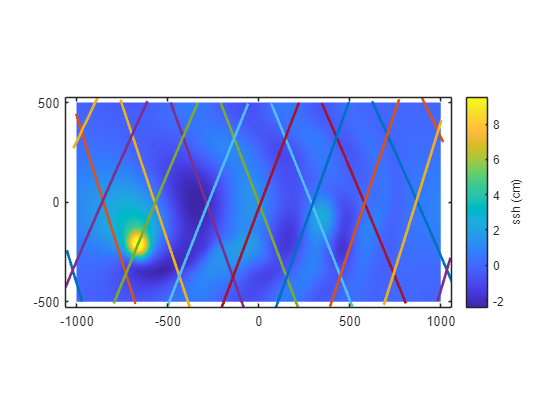

filename = 'BetaEddyOne.nc';
x = ncread([readdir, filename], 'x') / 1000; %km
y = ncread([readdir, filename], 'y') / 1000;
ssh = squeeze(ncread([readdir, filename], 'ssh'))*100;%cm;% matrix order in x,y,z
totalDays = size(ssh, 3);
totalCycles=round(totalDays/9.915645);
%redefine x and y to be centered on the domain midpoint
xc = x - mean(x);
yc = y - mean(y);

%extract a subset of tracks

%first, grid x and y
[xg, yg] = ndgrid(xc, yc);

%covert these to longitude and latitude using a tangent plane
[latg, long] = xy2latlon(xg, yg, lato, lono); %spehrical geometry
%cylindrical coordinate with axis on the equator
% [latg,long] = TransverseMercatorToLatitudeLongitude(xg,yg,lon0=lono);
% % Normalize longitude to [-180, 180] range
% long = mod(long + 180, 360) - 180;
% latg = mod(latg + 180, 360) - 180;

%create a region enclosing minima and maxima lon and lat
region = [min(long(:)), max(long(:)), min(latg(:)), max(latg(:))];

%extract latitude and longitude for this region; t is for track
[latt, lont, timet] = trackextract(lat, lon, time, region);
timet=timet(:,:,1:totalCycles);
lont = deg180(lont-lono) + lono; %avoids unwrapping issues

%finally, convert these latitudes and longitudes back to x and y
[xt, yt] = latlon2xy(latt, lont, lato, lono);

figure, jpcolor(xc, yc, ssh(:, :, end)'), hold on
plot(xt, yt, linewidth = 2), axis tight, latratio(lato), c=colorbar('EastOutside');c.Label.String = 'ssh (cm)';

## Eddy-centered x,y track matrix

load('center_SSHMax.mat', 'center_xy')
%% 90 percent sshmax center
% [center_xy, ~]=findSSHMaxContour(x,y,ssh); 
%% zeta-zero contour centroid
% [center_xy, core_xy]=findCenterZeroZeta(x,y,zeta2D,ssh2D);

## Interpolate ssht per day from the model ssh

[xMat,yMat,tMat]=ndgrid(xc,yc,[1:totalDays]);

%offset timet to start from day 1
timet1=floor(timet-min(timet(:))) + 1;

xtMat=repmat(xt,[1,1,totalCycles]);
ytMat=repmat(yt,[1,1,totalCycles]);
ssht = interpn(xMat,yMat,tMat, ssh, xtMat, ytMat,timet1, 'linear', 0);

xEt=nan(size(xtMat));
yEt=nan(size(ytMat));
for n = 1:totalDays
xEt(timet1==n)=xtMat(timet1==n)-(center_xy(n,1)-mean(x));
yEt(timet1==n)=ytMat(timet1==n)-(center_xy(n,2)-mean(y));
end

## 2D statistics

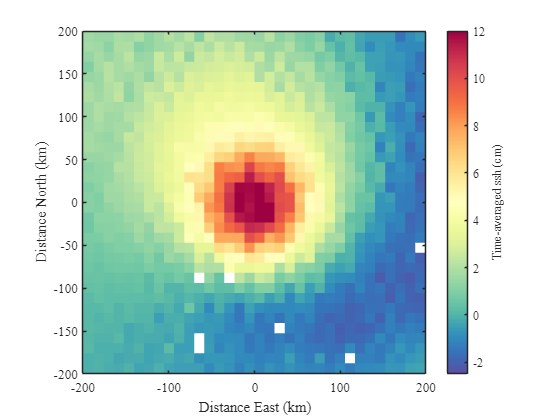

% define the bins
dbindeg = 10; %degree
dbin = round(dbindeg/(x(2) - x(1))); %index
dx = dbin * (x(2) - x(1)); %km
xEbound = min(abs([min(xEt(:)), max(xEt(:)), 250]));
xEbin = [fliplr([0:-dx:-xEbound]), dx:dx:xEbound];
yEbin = xEbin;

[mz2,xmid2,ymid2,numz2,stdz2]=twodstats(xEt(:), yEt(:),ssht(:), xEbin, yEbin);

% mean ssh 2D
figure;
jpcolor(xmid2, ymid2, mz2)
% jpcolor(xEbin, yEbin, AvgsshAccumBin)
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c=colorbar('EastOutside');c.Label.String = 'Time-averaged ssh (cm)';
xlim([-200, 200]), ylim([-200, 200]);
clim([-2.5, 12])

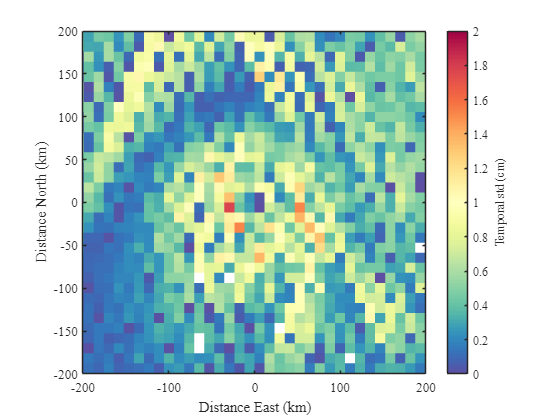


% plot 2D temporal std
figure;
jpcolor(xmid2, ymid2, stdz2);
% jpcolor(xEbin, yEbin, stdTemp2D);
shading flat
% hold on
% contour(xE,yE,stdTemp2D,[0:0.1:2],'k')
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c= colorbar('EastOutside');c.Label.String = 'Temporal std (cm)';
xlim([-200, 200]), ylim([-200, 200]); clim([0, 2])

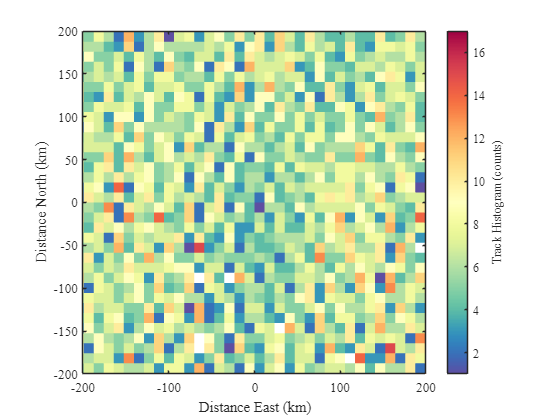

% 2D track counts histogram
figure;
numz2(numz2==0)=nan;
jpcolor(xmid2, ymid2, numz2)%
clim(round([min(numz2(:)), max(numz2(:))]))
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
c=colorbar('EastOutside'); c.Label.String = 'Track Histogram (counts)';
xlim([-200, 200]), ylim([-200, 200]);

## radialStatisticsFromScattered

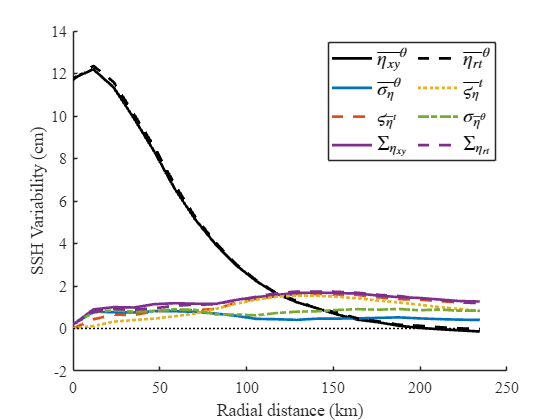

tbin = [0.5:1:totalDays+0.5]';%[1:totalDays]; %tbin for radialStatisticsFromScattered has to be per days for 'azimuthal'
rbin = [-dx/2:dx:xEbound]';
% Compute statistics
[mzxy, rmid, numz, stdAziAvgTemp, AvgAziStdTemp] = radialStatisticsFromScattered(xEt, yEt, timet1, ssht, rbin, tbin, firstAverage = 'temporal');
[mzrt, rmid, numz, stdTempAvgAzi, AvgTempStdAzi] = radialStatisticsFromScattered(xEt, yEt, timet1, ssht, rbin, tbin, firstAverage = 'azimuthal');
% Std Total
stdTotalxy = sqrt(stdAziAvgTemp.^2+AvgAziStdTemp.^2);
stdTotalrt = sqrt(stdTempAvgAzi.^2+AvgTempStdAzi.^2);

%plot profile
prettyblue = [0, 0.4470, 0.7410];
prettyorange = [0.8500, 0.3250, 0.0980];
prettyyellow = [0.9290, 0.6940, 0.1250];
prettypurple = [0.4940, 0.1840, 0.5560];
prettygreen = [0.4660, 0.6740, 0.1880];

figure; hold on
h1 = plot(rmid, mzxy, 'LineWidth', 2, 'Color', 'k', 'linestyle', '-');
h2 = plot(rmid, AvgAziStdTemp, 'LineWidth', 2, 'Color', prettyblue, 'linestyle', '-');
h3 = plot(rmid, stdAziAvgTemp, 'LineWidth', 2, 'Color', prettyorange, 'linestyle', '--');
h4 = plot(rmid, stdTotalxy, 'LineWidth', 2, 'Color', prettypurple, 'linestyle', '-');
h5 = plot(rmid, mzrt, 'LineWidth', 2, 'Color', 'k', 'linestyle', '--');
h6 = plot(rmid, AvgTempStdAzi, 'LineWidth', 2, 'Color', prettyyellow, 'linestyle', ':');
h7 = plot(rmid, stdTempAvgAzi, 'LineWidth', 2, 'Color', prettygreen, 'linestyle', '-.');
h8 = plot(rmid, stdTotalrt, 'LineWidth', 2, 'Color', prettypurple, 'linestyle', '--');

xlabel('Radial distance (km)', 'FontName', 'times')
ylabel('SSH Variability (cm)', 'FontName', 'times')
set(gca, 'fontname', 'times')
% % zero horizontal line
plot([rmid(1), rmid(end-1)], [0, 0], 'k:')
lg = legend([h1, h2, h3,h4, h5, h6, h7,h8], '$\overline{\eta_{xy}}^\theta$', '$\overline{\sigma_\eta}^\theta$', '$\varsigma_{\overline{\eta}^t}$','$\Sigma_{\eta_{xy}}$','$\overline{\eta_{rt}}^\theta$', '$\overline{\varsigma_\eta}^t$', '$\sigma_{\overline{\eta}^\theta}$', '$\Sigma_{\eta_{rt}}$');
set(lg, 'interpreter', 'latex', 'fontsize', 15, 'orientation', 'vertical','NumColumns',2)
set(gca, 'fontsize', 12)
xlim([0, 250]); ylim([-2, 14])

## r vs t directly from track

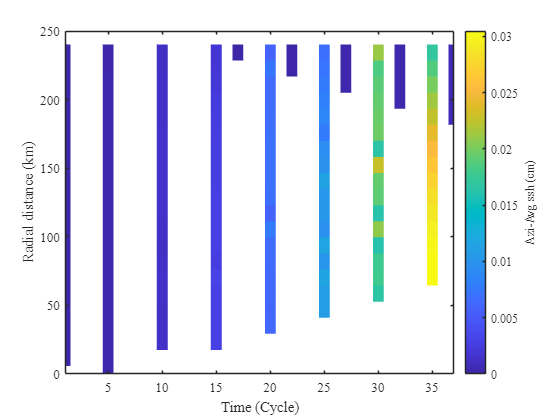

center_i=center_xy(1,:);
center_n=center_xy(n,:);
x0=center_xy(:,1)-center_i(1);
y0=center_xy(:,2)-center_i(2);

rt=nan(size(xtMat));
for n = 1:totalDays
rt(timet1==n) = sqrt((x0(n)-xtMat(timet1==n)).^2+(y0(n)-ytMat(timet1==n)).^2);
end

cycbin = [0.5:1:totalCycles+0.5]';

[mz_rt,rmid,~,numz_rt,stdz_rt]=twodstats(rt,timet1,ssht,rbin,cycbin);

figure; hold on;
% mzrt_norm =  mz_rt/max(mz_rt(:));
jpcolor([1:totalCycles],rmid,mz_rt')
xlim([1,totalCycles]),ylim([0,250])
xlabel('Time (Cycle)', 'FontName', 'times')
ylabel('Radial distance (km)', 'FontName', 'times')
c=colorbar('EastOutside'); c.Label.String = 'Azi-Avg ssh (cm)';
set(gca, 'fontname', 'times')